%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% AUDIO_DIGIT_ANALYSIS_META3.M
%
% Script for Audio Digit Analysis - Meta 3
% Tasks:
% 16) Load data structure from previous meta (finalAudioData.mat).
% 17) Considering the best extracted characteristics from the time and frequency signals
%     in the points 8 and 14, respectively, apply a classifier to automate the identification
%     of the digits through the characteristics.
% 18) Compare the atributed digits to each audio through the classifier used in the point 17
%     with the original digits and define the accuracy percentage of the classifier
%     (number of correctly classified digits / total number of digits * 100).
% 19) Compare the three different windows, applying them in time intervals
% 20)  Update the data structure file (finalAudioData.mat).
%
% Authors: [Teodoro Marques, Bernardo Direito]
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; close all; clc;

## INITIAL PARAMETERS

participantID = 40;             % Unique participant identifier
digitNumbers = 0:9;             % Digits from 0 to 9

## STAGE 16: LOAD DATA STRUCTURE FROM PREVIOUS META

load('finalAudioData.mat', 'metadataTable');
disp('Data structure loaded from finalAudioData.mat');

Data structure loaded from finalAudioData.mat


## STAGE 17: CLASSIFIER: Using random forest

% Combine the best features from time (Stage 8) and frequency (Stage 14)
% Assuming the best features are already identified:
% Time features: TotalEnergy, StandardDeviation
% Frequency features: SpecMaxAmp, SpecCentroid

% Extract features and labels obtained in stages 8 and 14
features = [metadataTable.TotalEnergy, metadataTable.StandardDeviation, ...
    metadataTable.SpecMaxAmp, metadataTable.SpecCentroid];
labels = metadataTable.DigitValue; % True digit labels

% Remove rows with missing or invalid data
validIndices = all(~isnan(features), 2) & ~isnan(labels);
features = features(validIndices, :);
labels = labels(validIndices);

% Split data into training (80%) and testing (20%) sets
cv = cvpartition(labels, 'HoldOut', 0.2);
trainFeatures = features(training(cv), :);
trainLabels = labels(training(cv));
testFeatures = features(test(cv), :);
testLabels = labels(test(cv));

% Train the random forest classifier using the fitcensemble function
% with Bagging method
randomForestModel = fitcensemble(trainFeatures, trainLabels, ...
    'Method', 'Bag', 'NumLearningCycles', 100, 'Learners', 'Tree');

% Predict the test set using the predict function
predictedLabels = predict(randomForestModel, testFeatures);

% Save the trained model for future use
save('randomForestModel.mat', 'randomForestModel');

## STAGE 18: COMPARE CLASSIFIER RESULTS WITH ORIGINAL DIGITS

% Display a comparison between predicted and true labels
comparisonTable = table(testLabels, predictedLabels, ...
    'VariableNames', {'TrueLabels', 'PredictedLabels'});
disp('Comparison of True and Predicted Labels:');

Comparison of True and Predicted Labels:


disp(comparisonTable);

    TrueLabels    PredictedLabels
    __________    _______________

        0                2       
        0                4       
        0                2       
        0                0       
        0                2       
        0                0       
        0                0       
        0                0       
        0                0       
        0                0       
        1                1       
        1                7       
        1                7       
        1                1       
        1                0       
        1                1       
        1                7       
        1                7       
        1                1       
        1                1       
        2                9       
        2                2       
        2                5       
        2                0       
        2                2       
        2    


% Calculate accuracy
accuracyPercentage = sum(predictedLabels == testLabels) / length(testLabels) * 100;
fprintf('Random Forest Classifier Accuracy: %.2f%%\n', accuracyPercentage);

Random Forest Classifier Accuracy: 56.00%



% Confusion matrix
confMatrix = confusionmat(testLabels, predictedLabels);
disp('Confusion Matrix:');

Confusion Matrix:


disp(confMatrix);

     6     0     3     0     1     0     0     0     0     0
     1     5     0     0     0     0     0     4     0     0
     1     1     4     0     0     3     0     0     0     1
     0     0     0     4     0     1     0     3     2     0
     1     0     0     0     9     0     0     0     0     0
     1     1     1     1     0     2     0     1     3     0
     0     0     0     0     0     0    10     0     0     0
     0     2     2     1     0     1     0     3     0     1
     0     0     1     0     0     0     0     0     9     0
     3     1     0     0     0     2     0     0     0     4



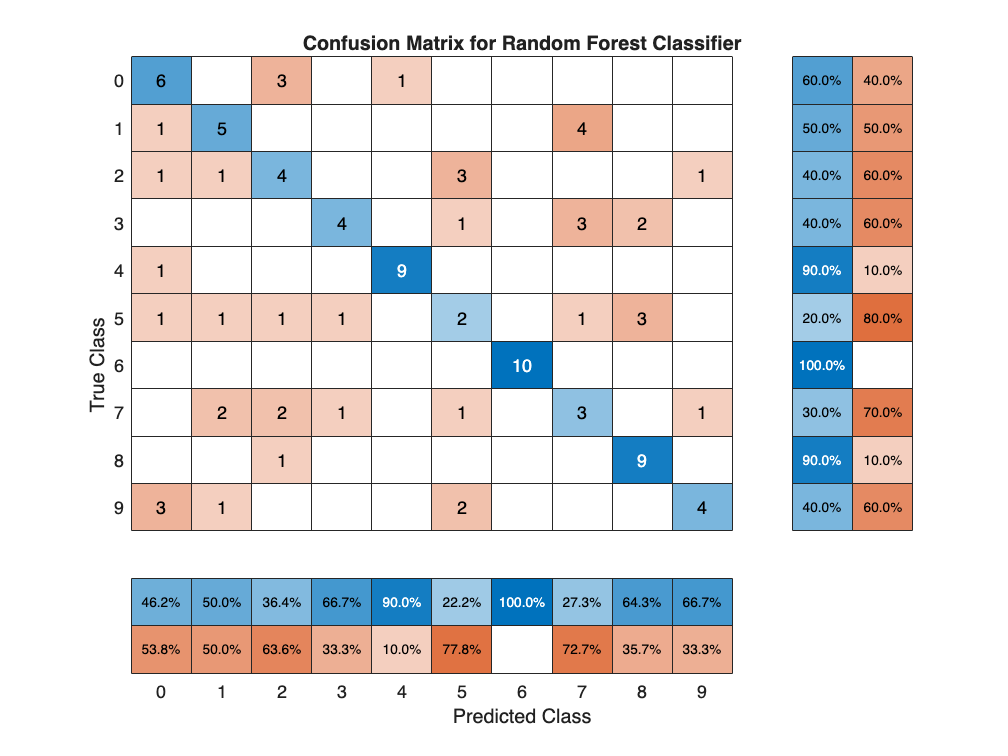


% Plot the confusion matrix
figure('Name', 'Confusion Matrix', 'NumberTitle', 'off');
confusionchart(confMatrix, digitNumbers, ...
    'Title', 'Confusion Matrix for Random Forest Classifier', ...
    'RowSummary', 'row-normalized', 'ColumnSummary', 'column-normalized');

## STAGE 19: COMPARE THREE DIFFERENT WINDOWS

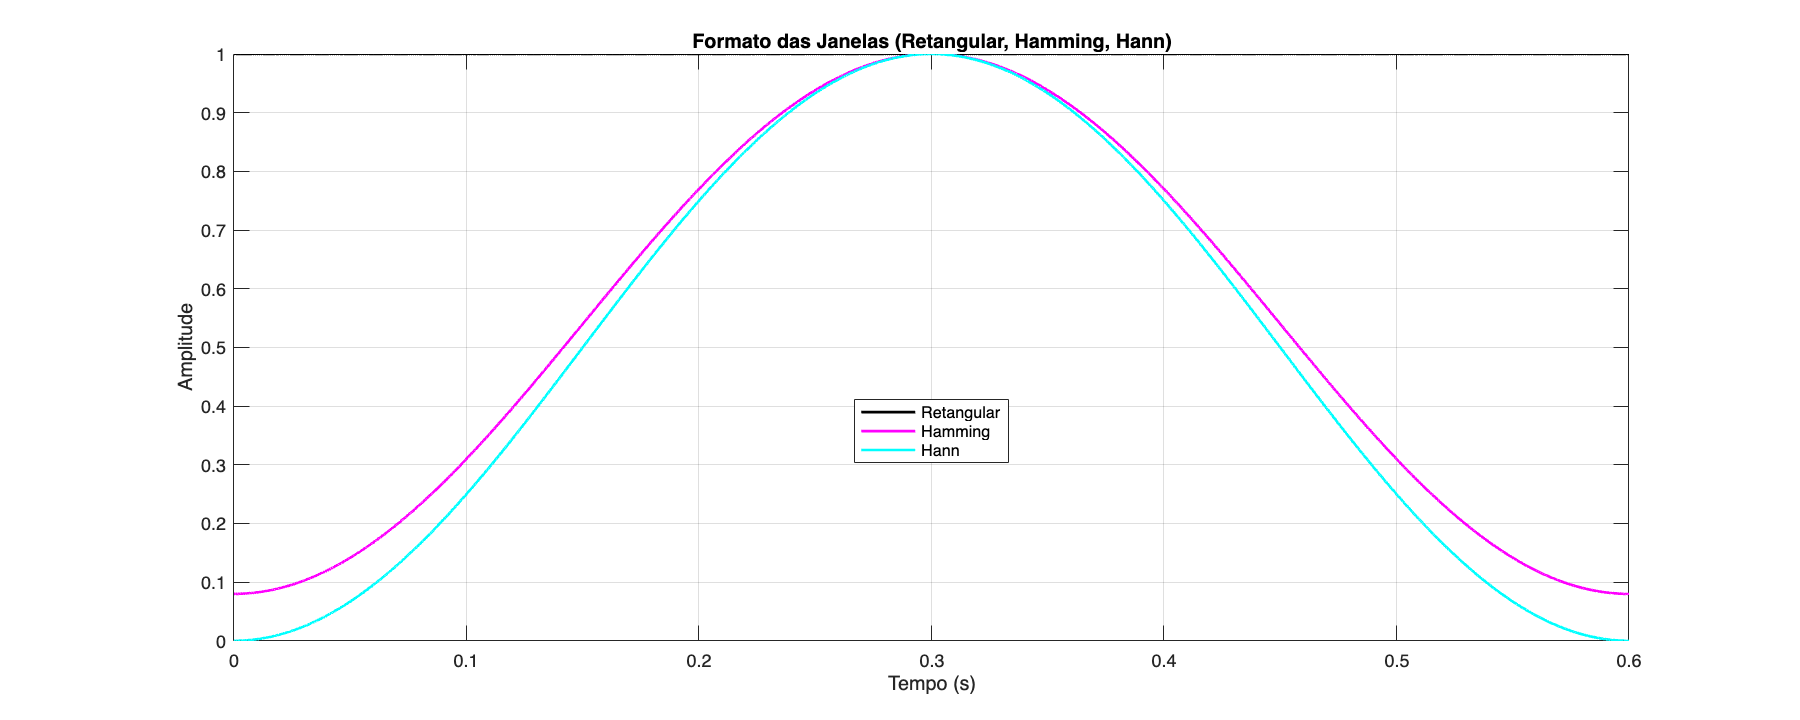

%% STAGE 19: FORMATO DE JANELAS E ESPECTROS POR DÍGITO
% — análise do formato das janelas e seus espectros, para cada dígito

% 1) Plota o formato das 3 janelas num sinal de exemplo
s0  = metadataTable.PreprocessedAudioSignal{1};
fs0 = metadataTable.SamplingRate(1);
N0  = length(s0);
t0  = (0:N0-1)/fs0;

w_rect0    = ones(N0,1);
w_hamming0 = hamming(N0);
w_hann0    = hann(N0);

figure('Name','Formato das Janelas','NumberTitle','off','Position',[100 100 1000 400]);
plot(t0, w_rect0,    'k', 'LineWidth',1.5); hold on;
plot(t0, w_hamming0, 'm', 'LineWidth',1.5);
plot(t0, w_hann0,    'c', 'LineWidth',1.5);
title('Formato das Janelas (Retangular, Hamming, Hann)');
xlabel('Tempo (s)'); ylabel('Amplitude');
legend('Retangular','Hamming','Hann','Location','best');
grid on;

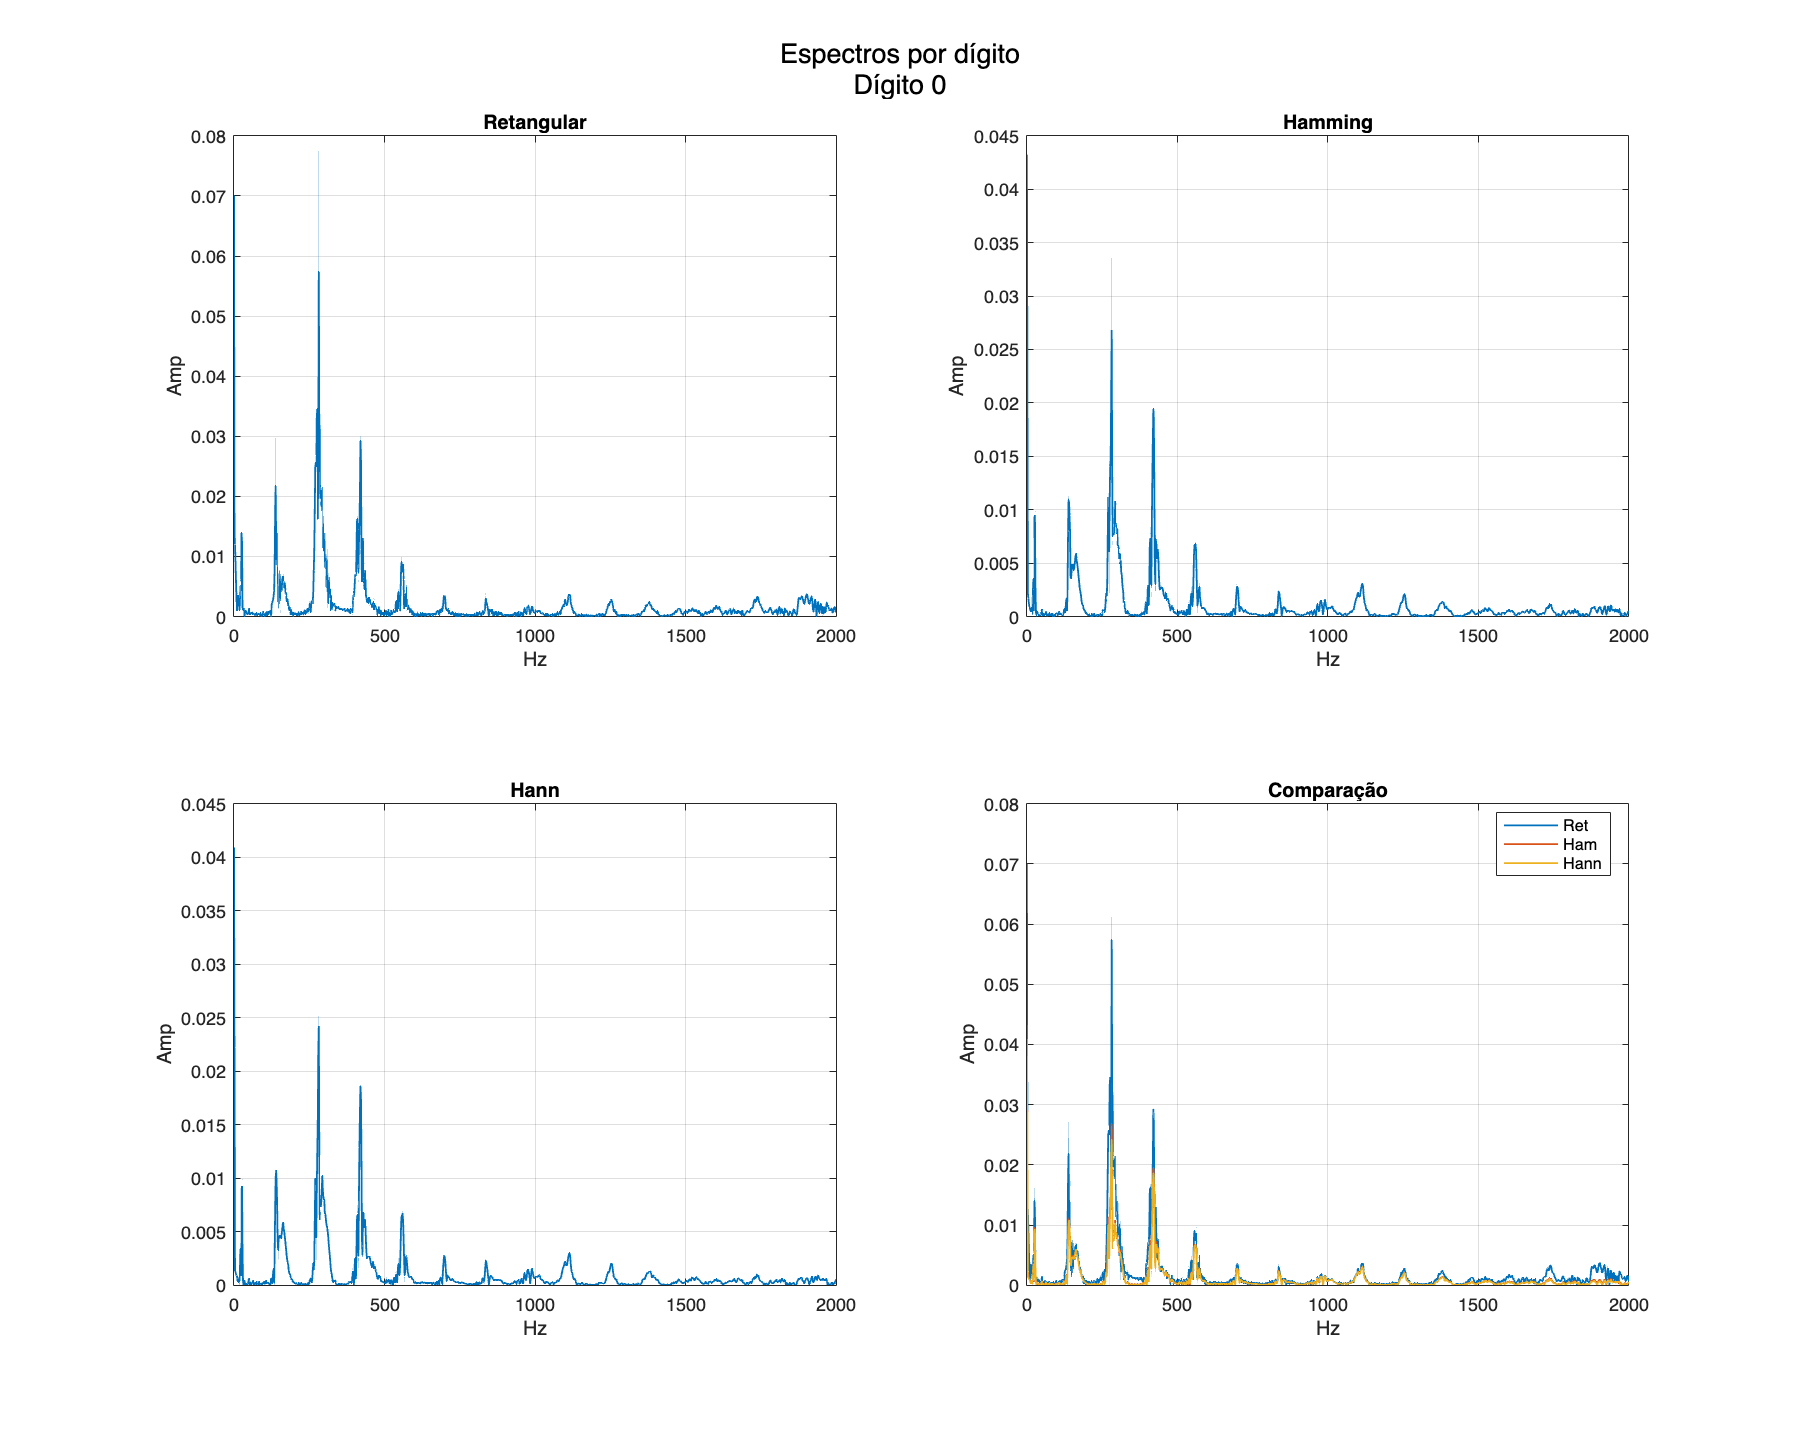

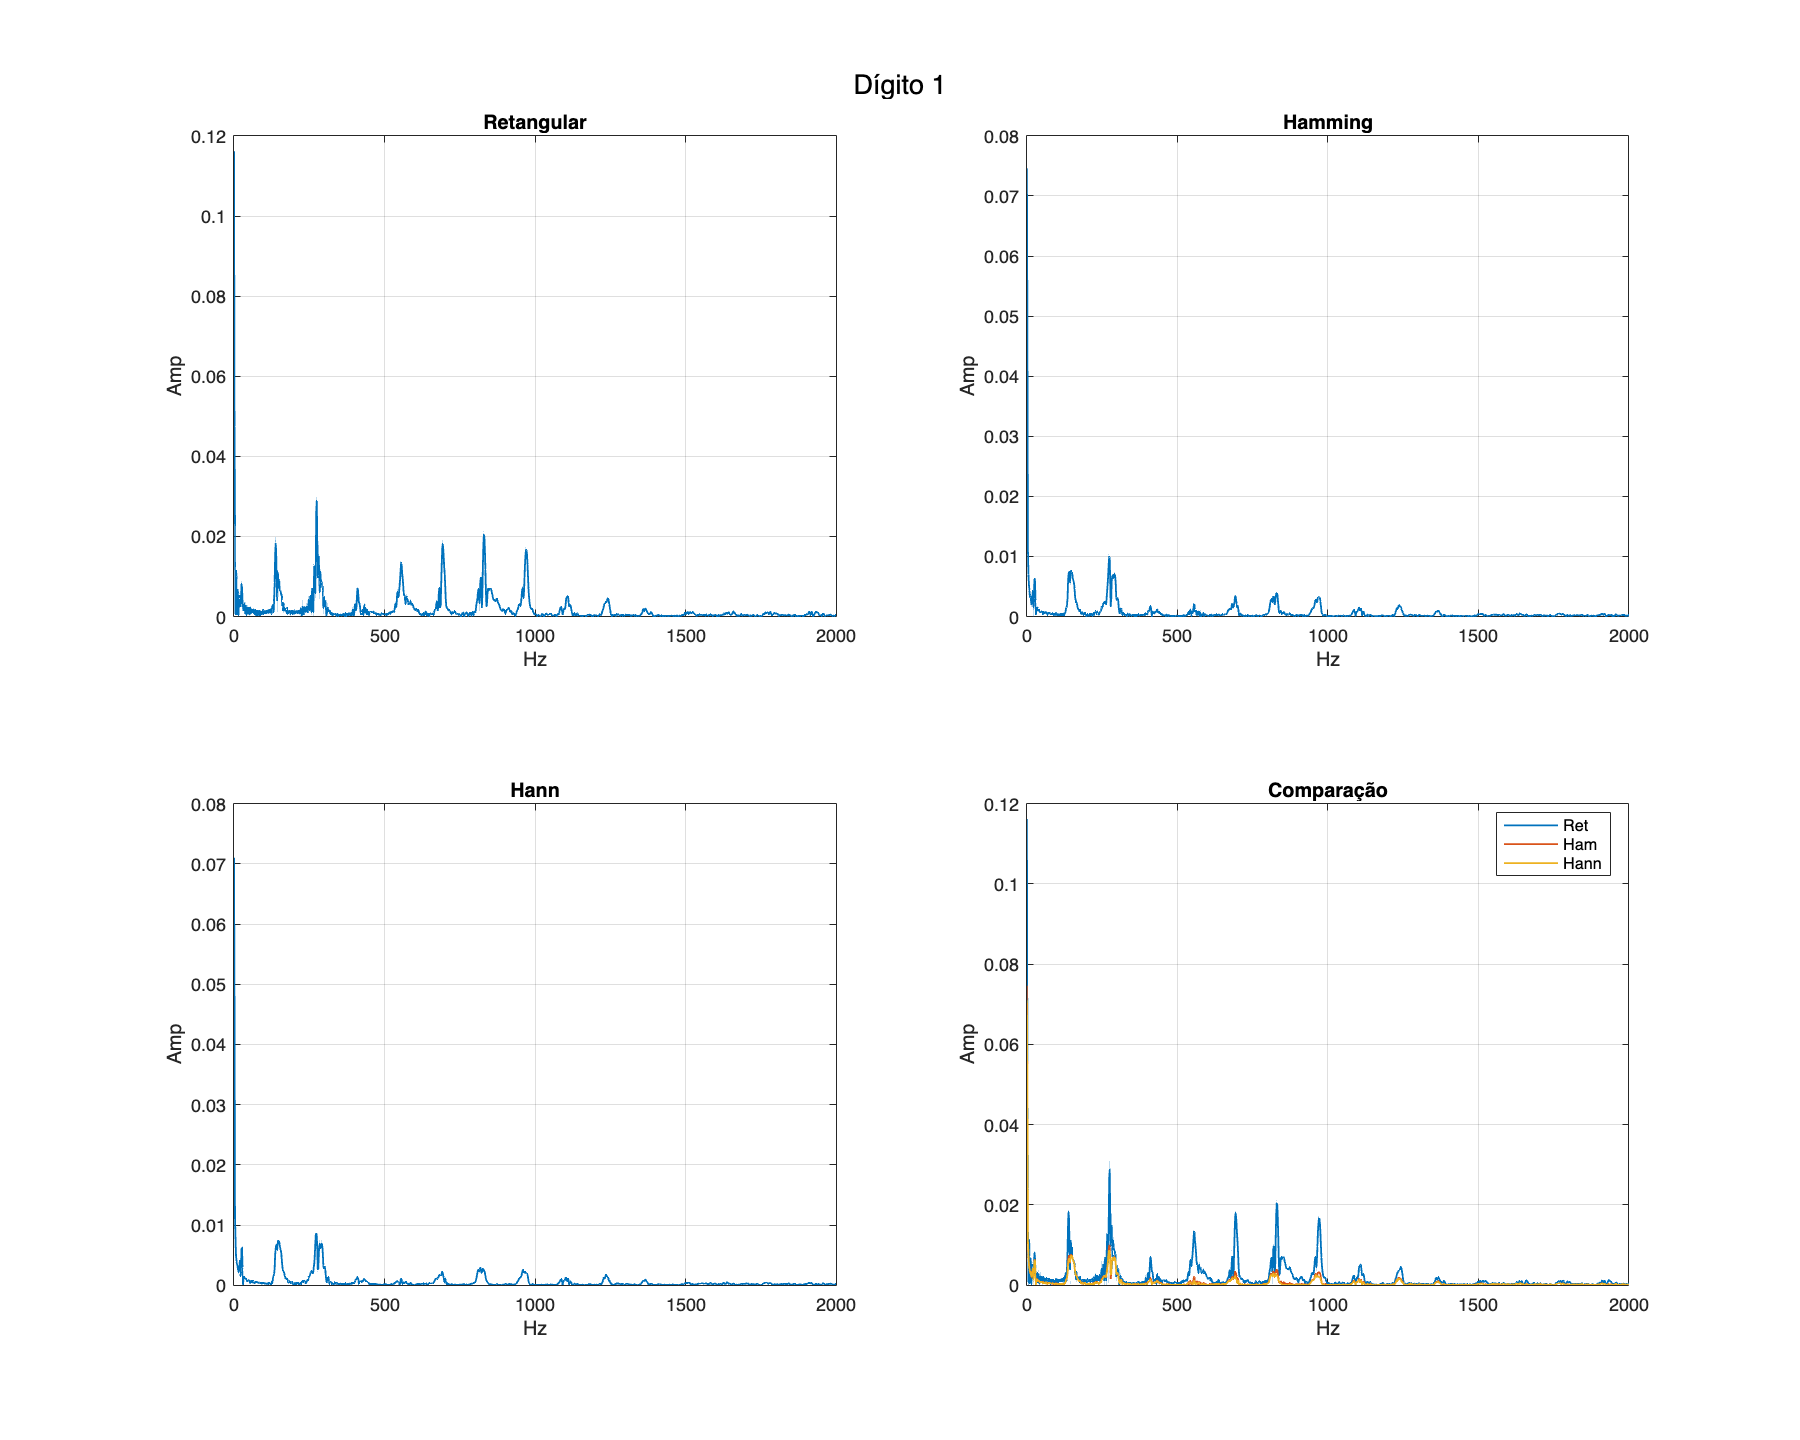

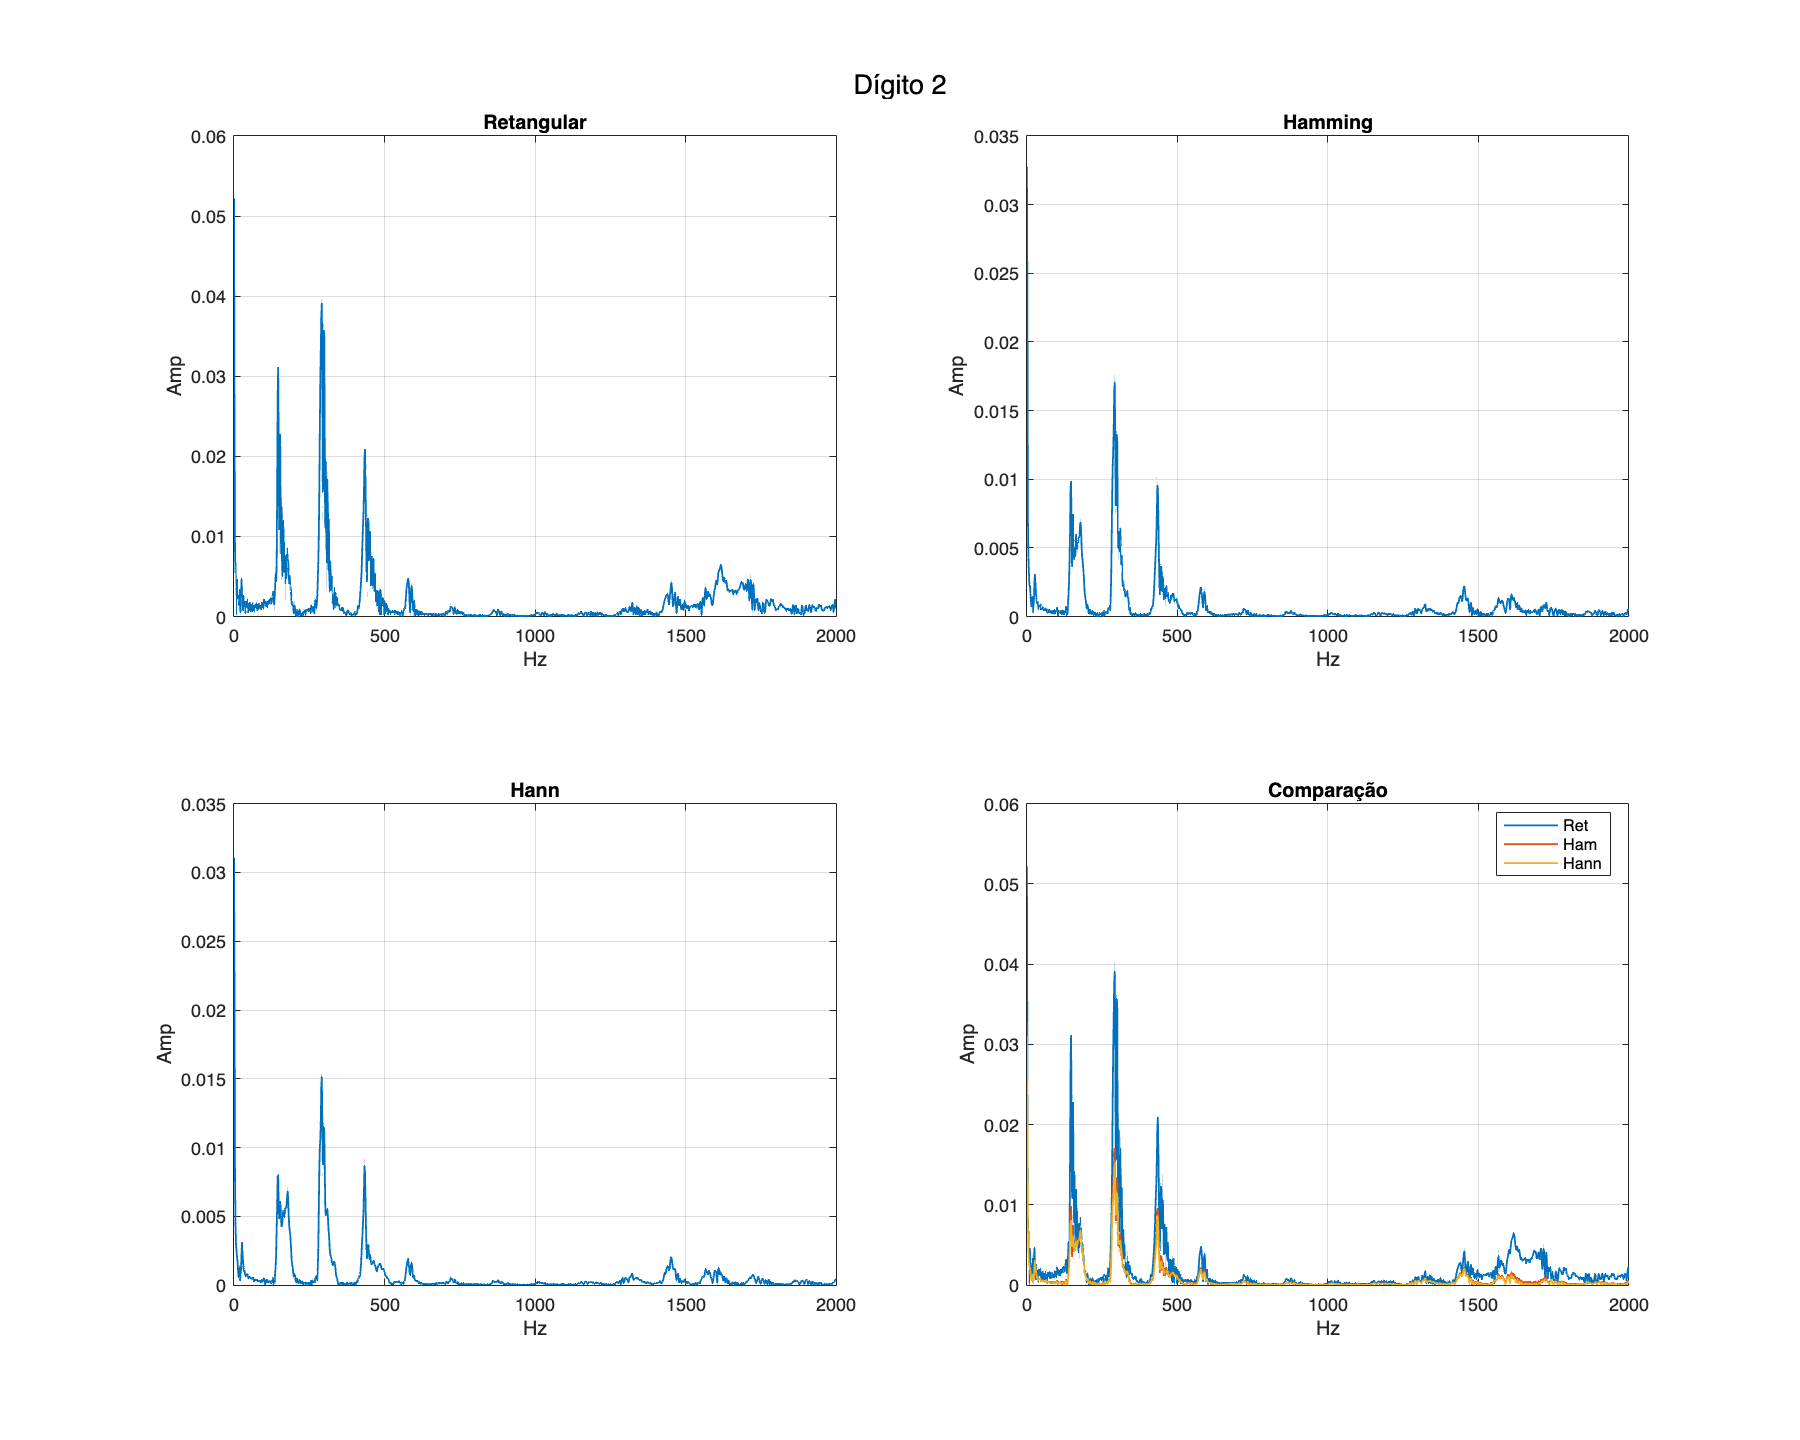

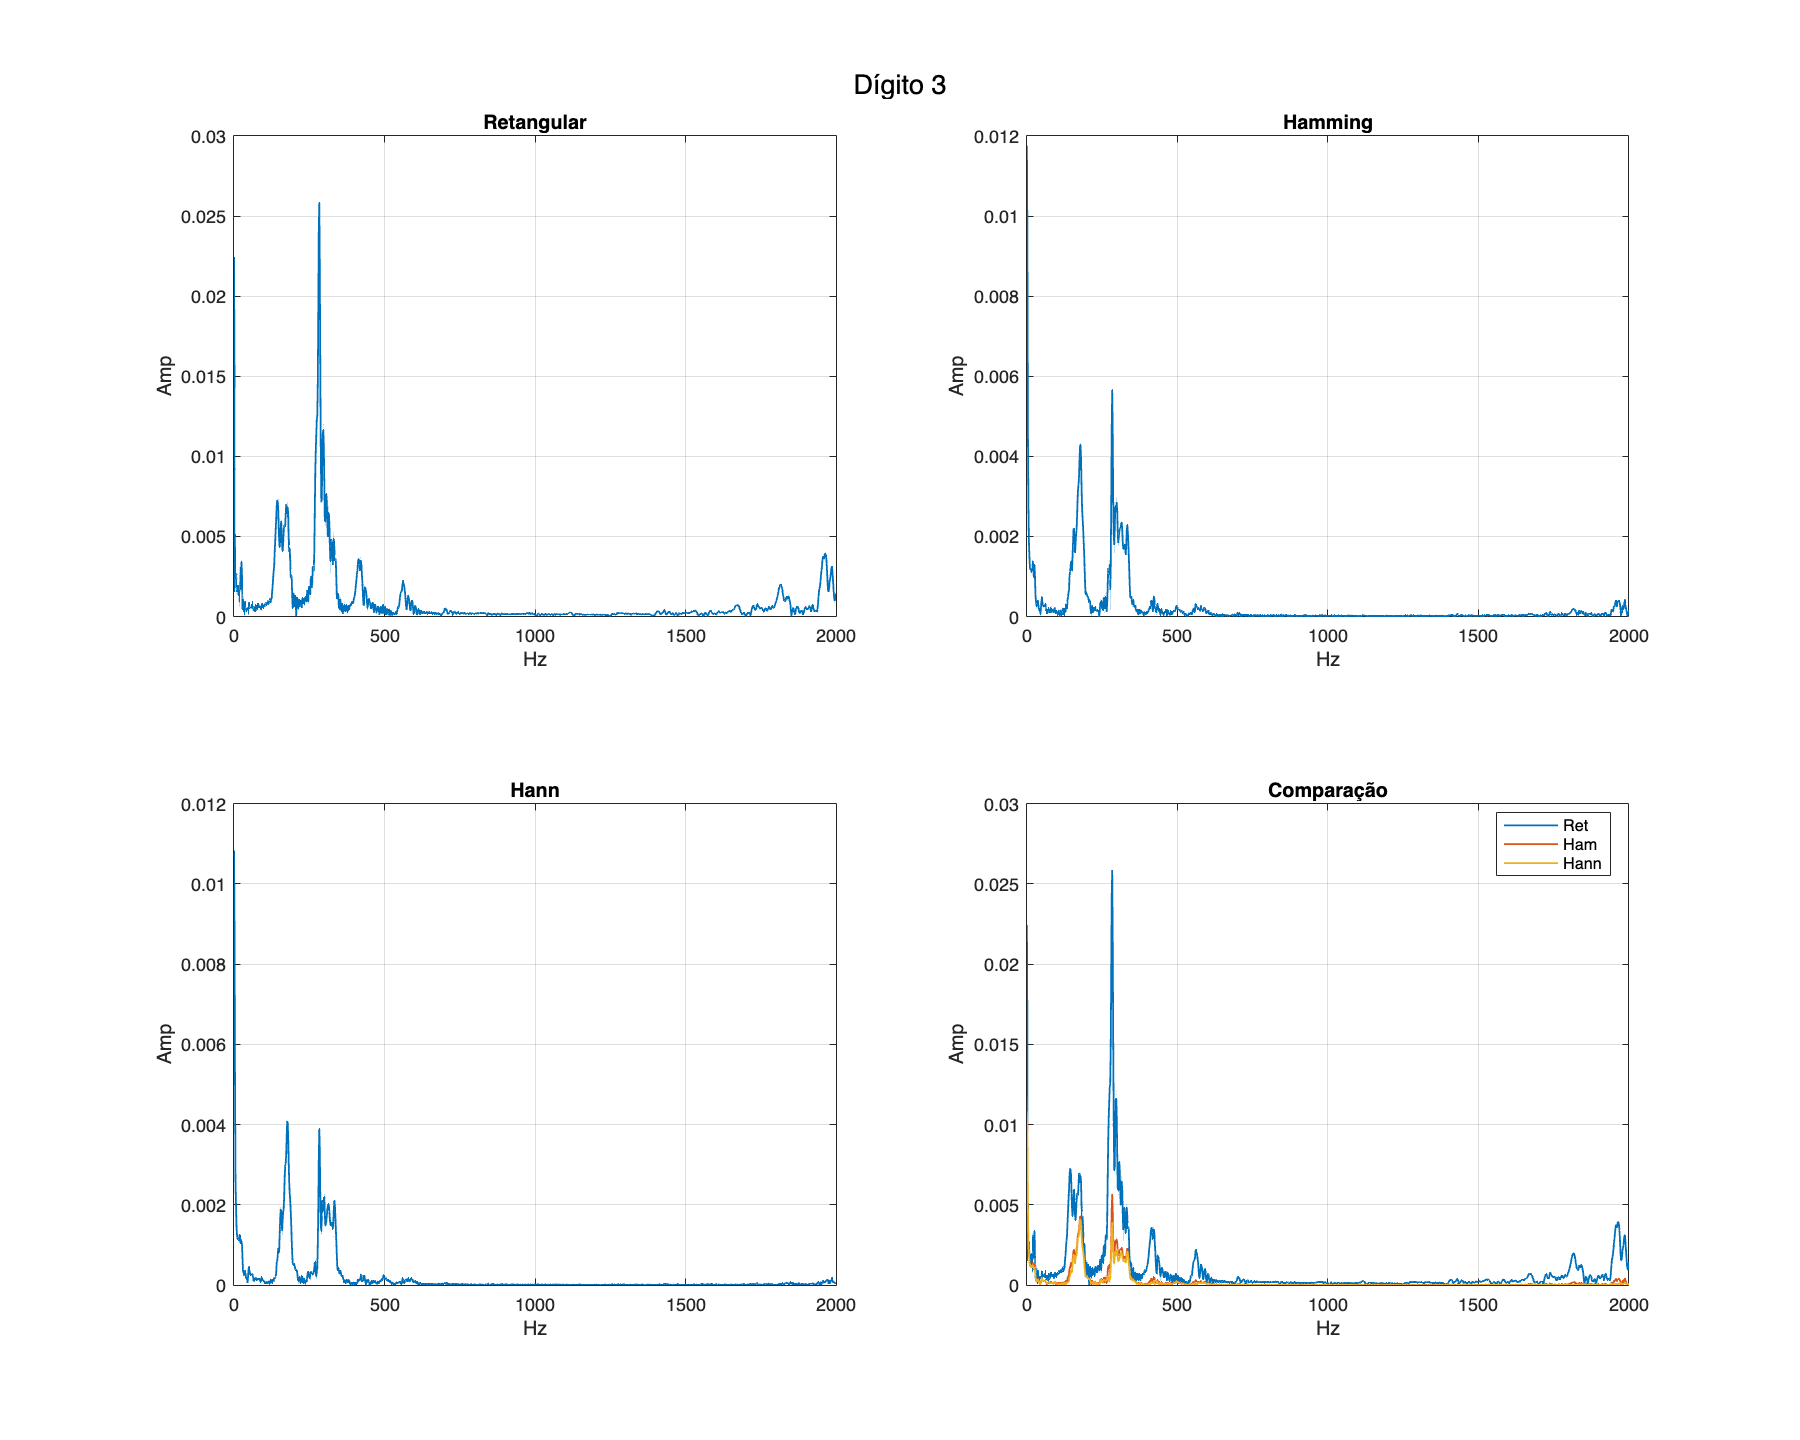

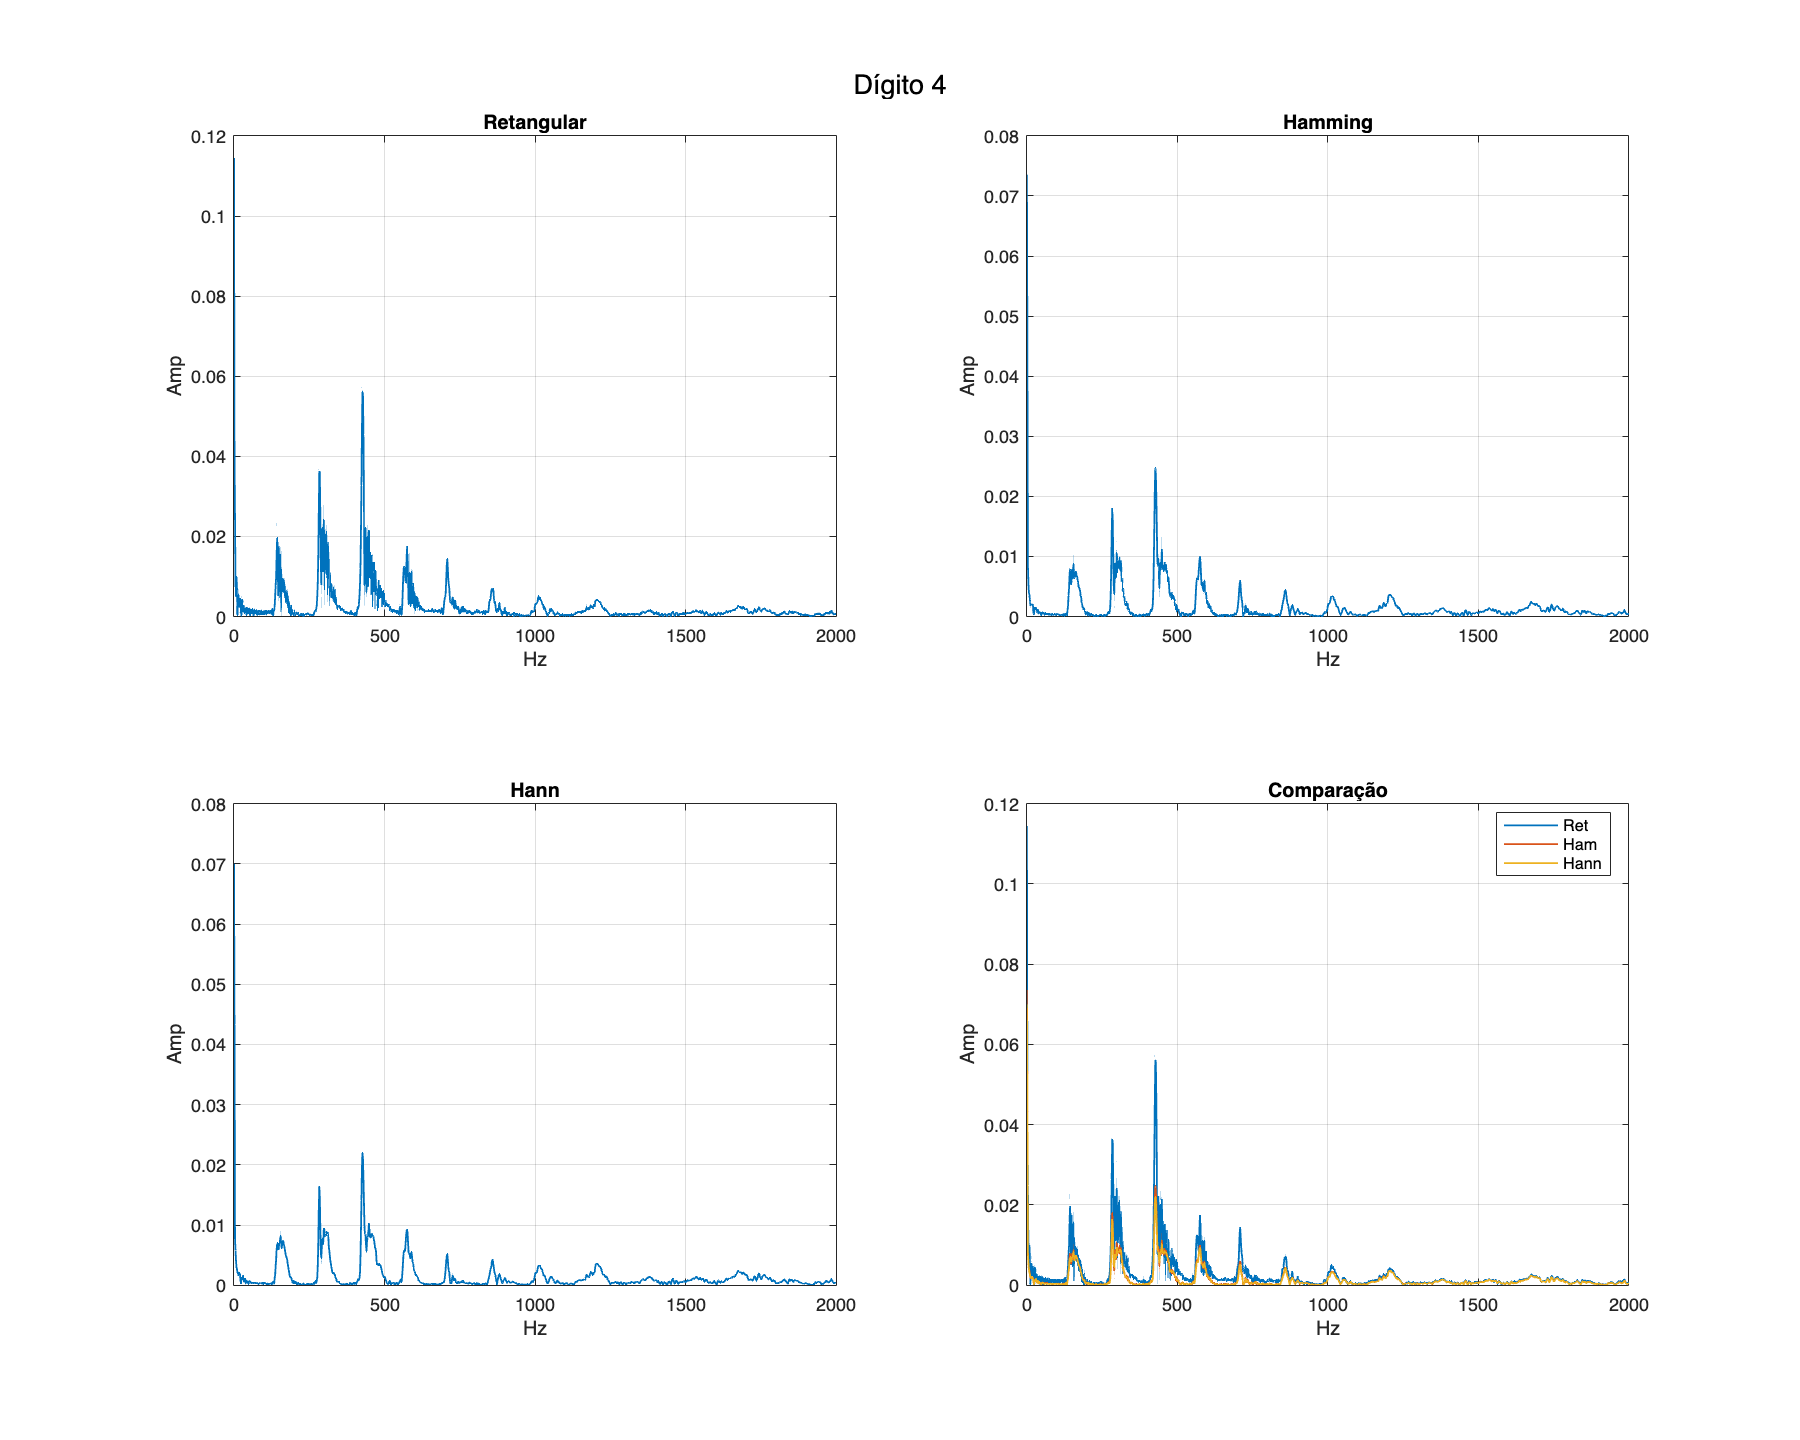

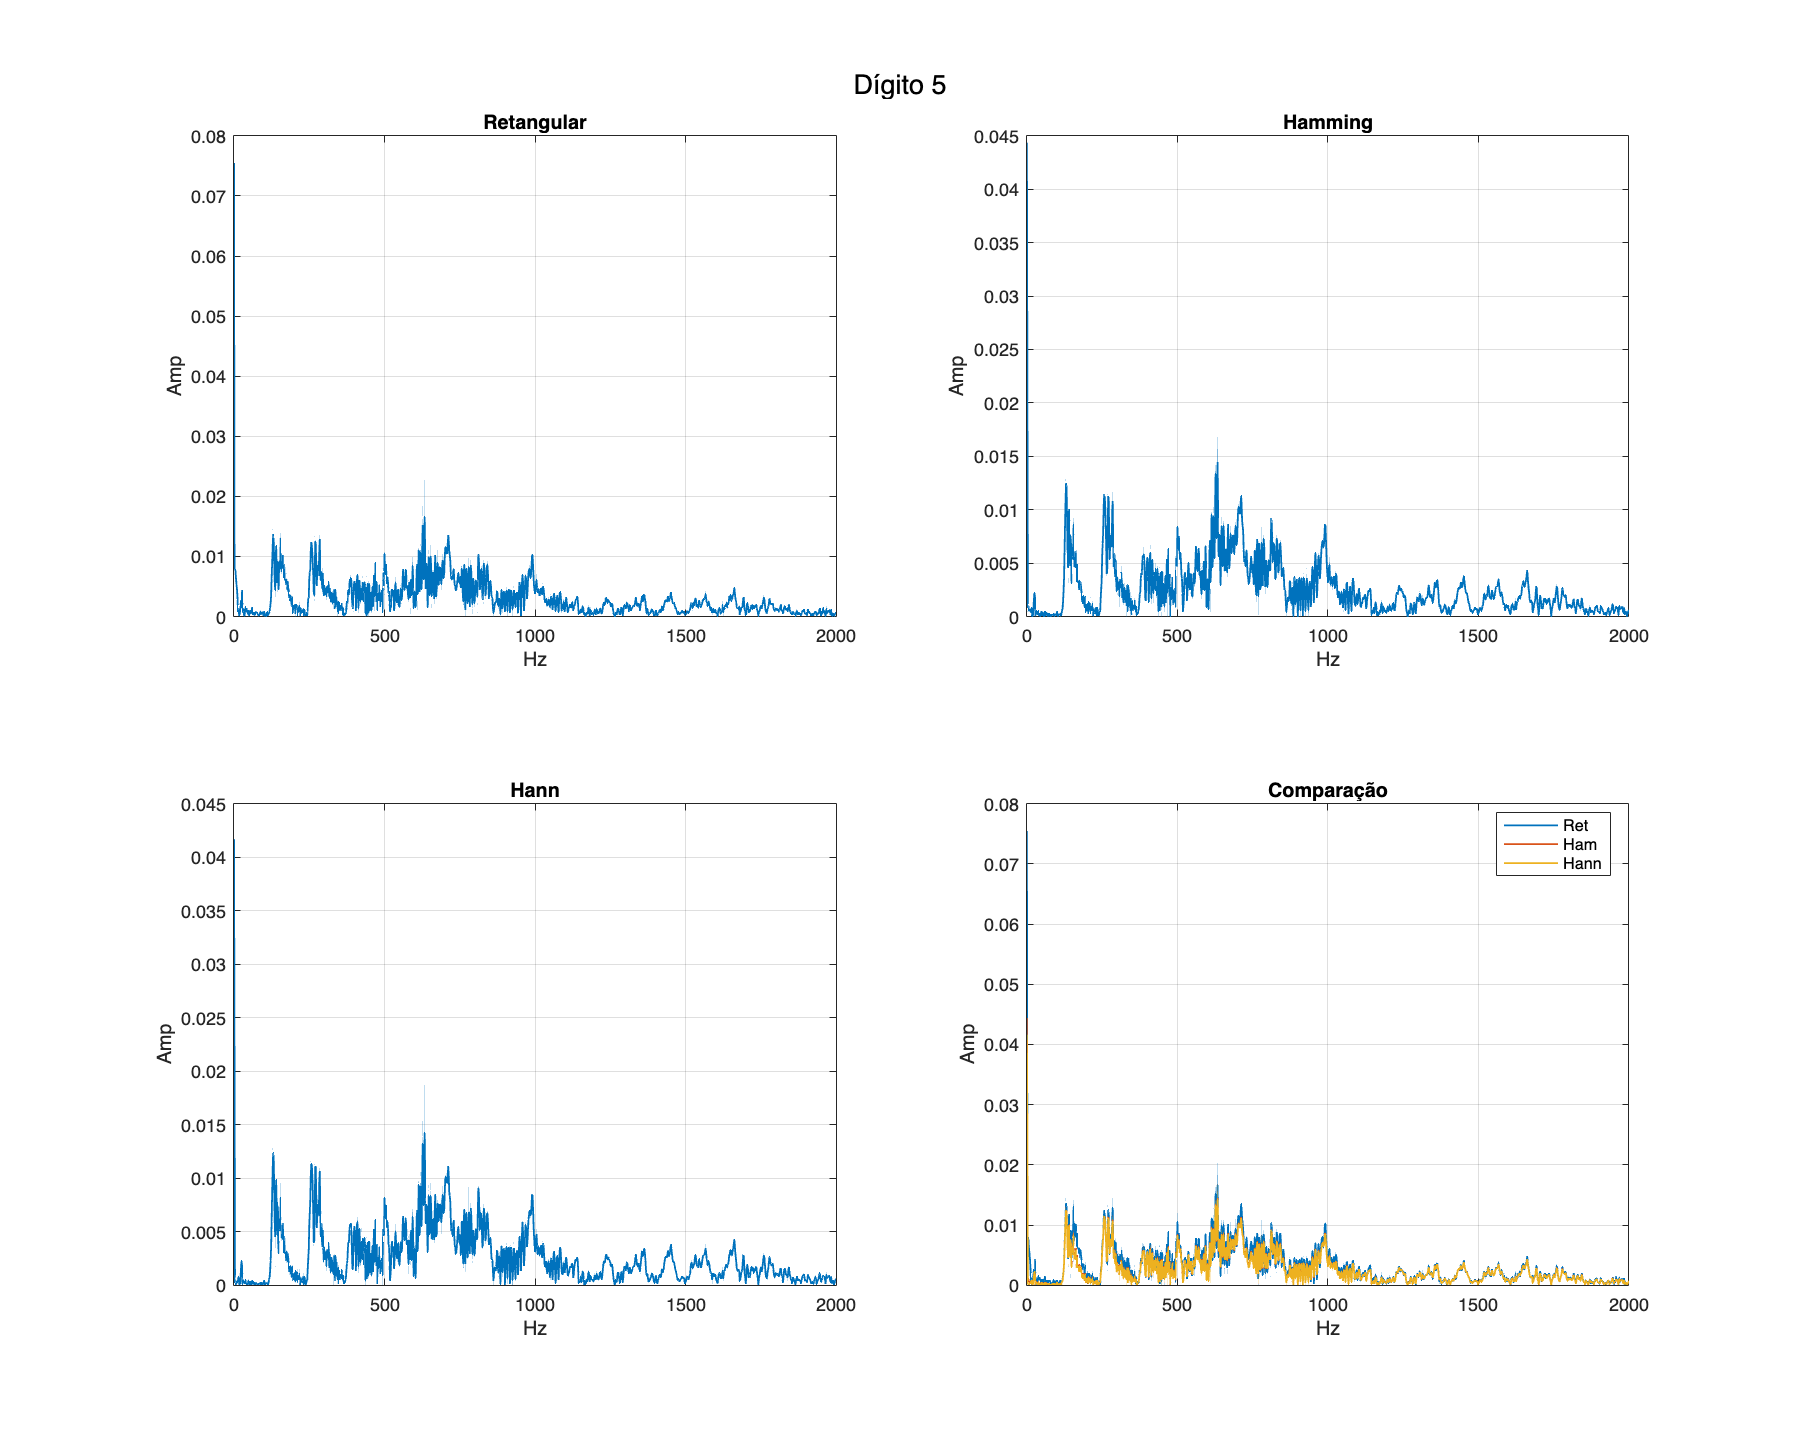

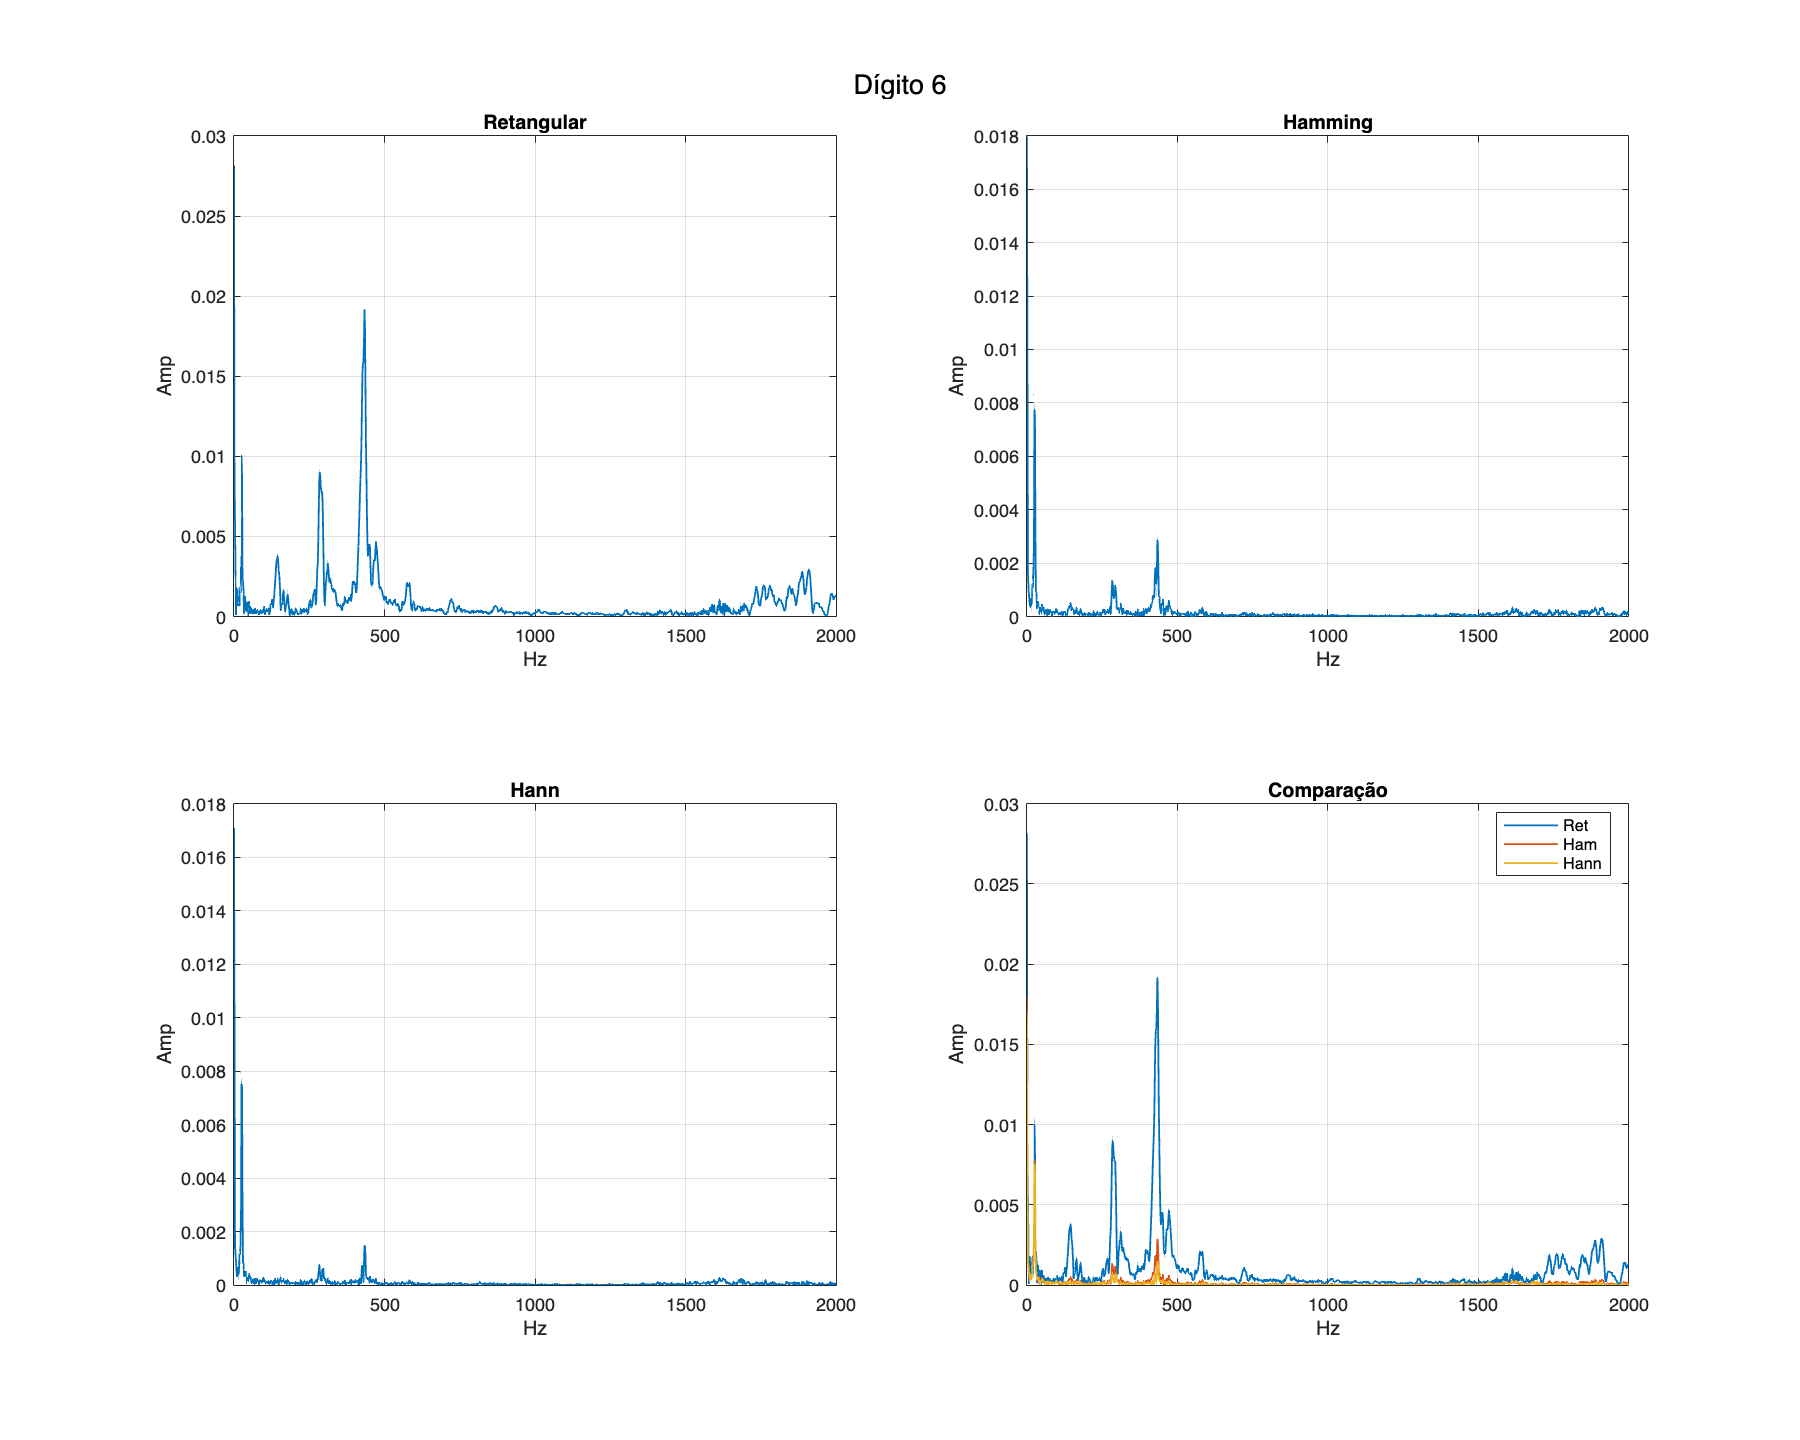

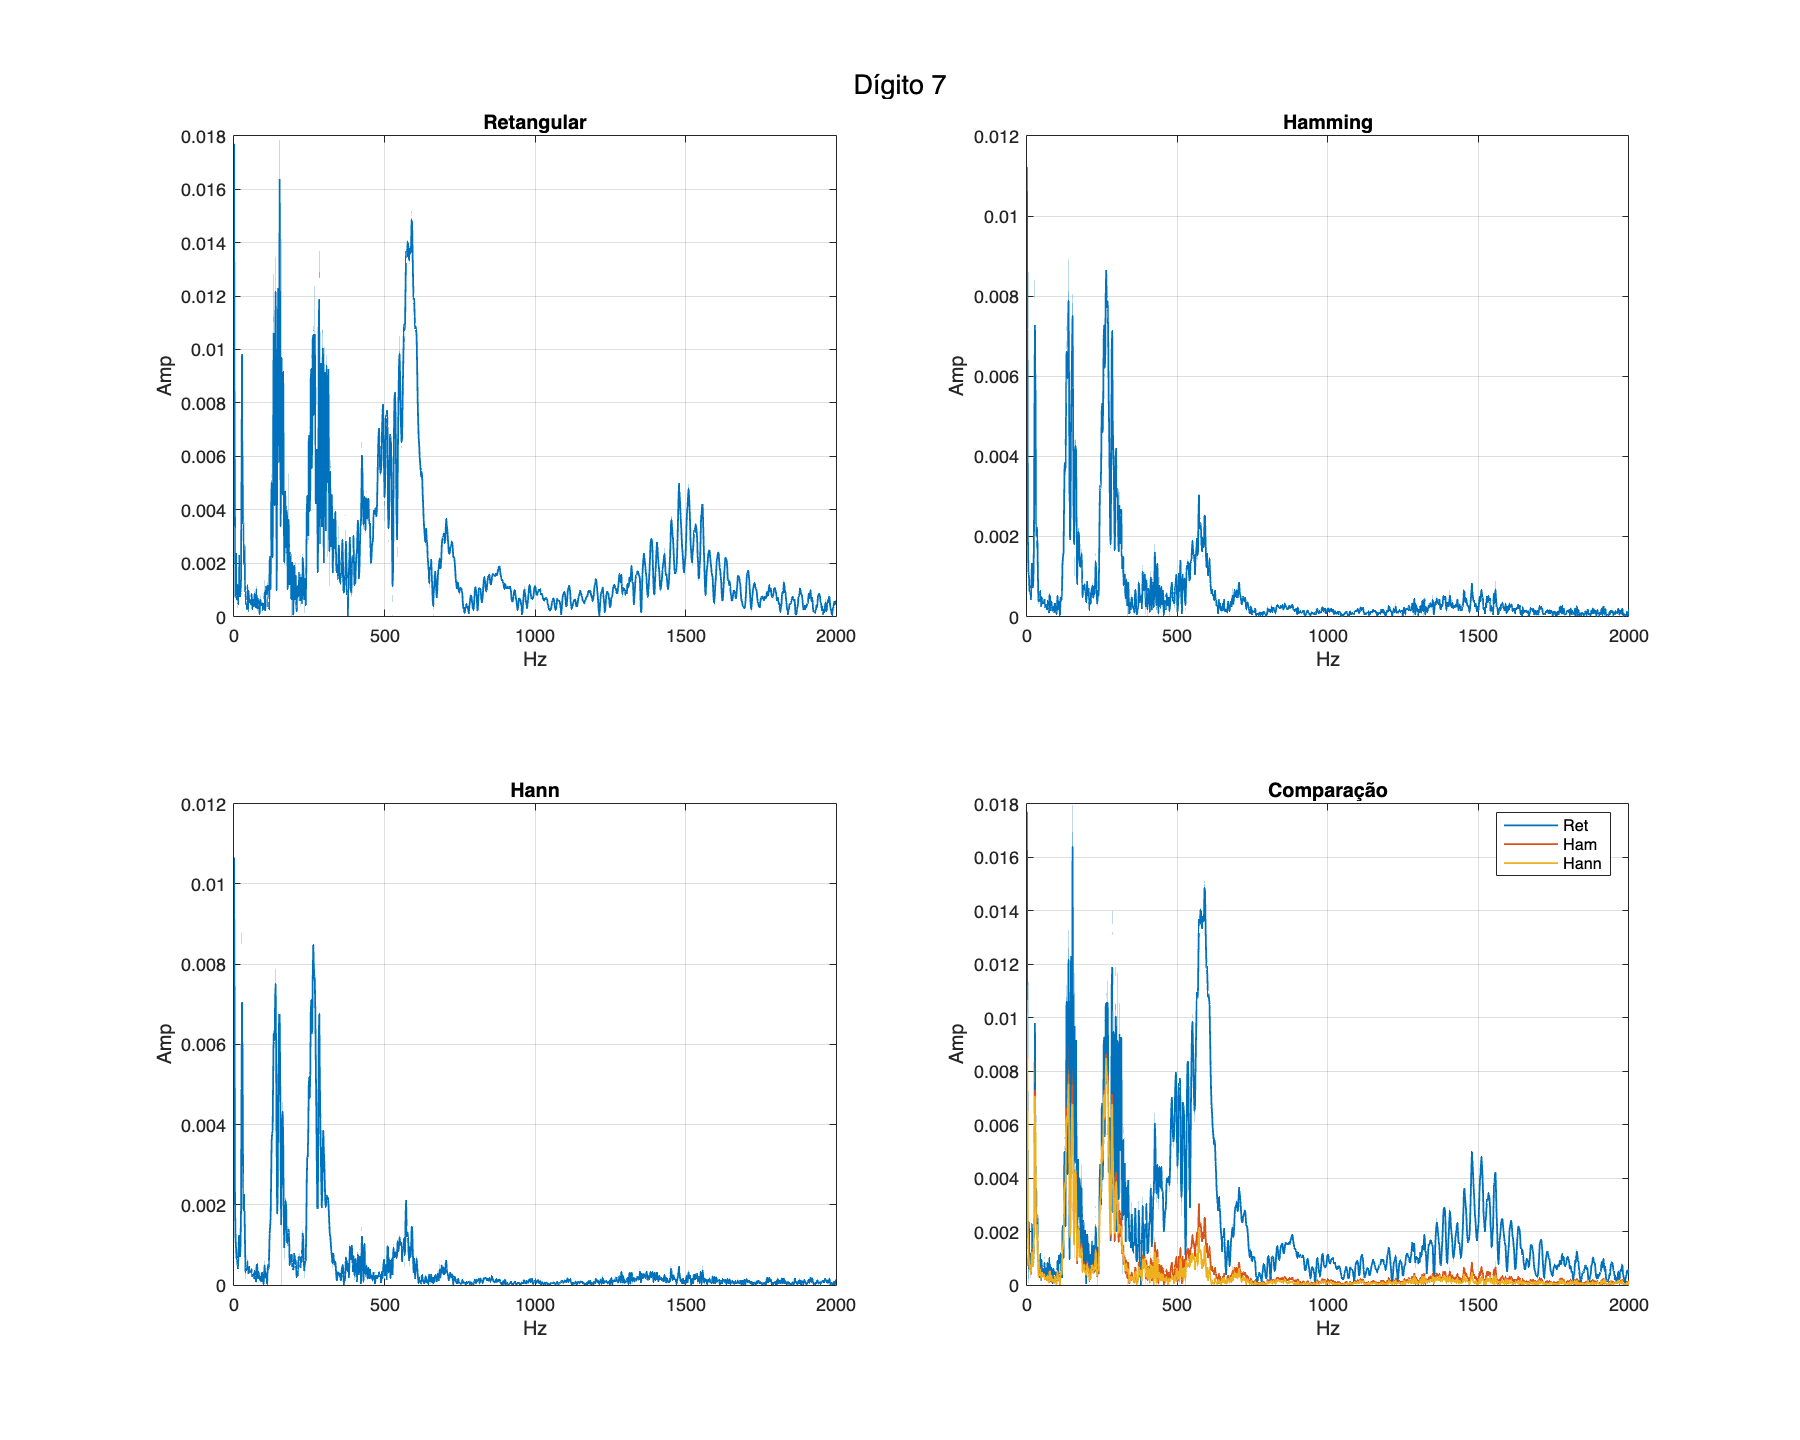


% 2) Para cada dígito, aplica as janelas, calcula FFT e plota espectros
digitos_all = unique(metadataTable.DigitValue);
for k = 1:numel(digitos_all)
    d = digitos_all(k);
    idx = find(metadataTable.DigitValue == d, 1);

    % sinal e fs desse dígito
    s  = metadataTable.PreprocessedAudioSignal{idx};
    fs = metadataTable.SamplingRate(idx);
    N  = length(s);

    % janelas
    w_rect    = ones(N,1);
    w_hamming = hamming(N);
    w_hann    = hann(N);

    % FFT normalizada
    S_rect    = fft(s .* w_rect)    / N;
    S_hamming = fft(s .* w_hamming) / N;
    S_hann    = fft(s .* w_hann)    / N;

    % vetor de frequência até 2000 Hz
    nFreq   = floor(N/2) + 1;
    freq    = (0:nFreq-1) * fs / N;
    idx2000 = freq <= 2000;
    f2000   = freq(idx2000);

    % amplitudes
    ampR = abs(S_rect(1:nFreq));    ampR = ampR(idx2000);
    ampH = abs(S_hamming(1:nFreq)); ampH = ampH(idx2000);
    ampN = abs(S_hann(1:nFreq));    ampN = ampN(idx2000);

    % plot
    figure('Name',sprintf('Dígito %d - Espectros de Janelas',d), ...
           'NumberTitle','off','Position',[100 100 1000 800]);
    if k == 1
        sgtitle({'Espectros por dígito', sprintf('Dígito %d', d)});
    else
        sgtitle(sprintf('Dígito %d', d));
    end

    subplot(2,2,1);
    plot(f2000, ampR, 'LineWidth',1);
    title('Retangular');    xlabel('Hz'); ylabel('Amp'); xlim([0 2000]); grid on;

    subplot(2,2,2);
    plot(f2000, ampH, 'LineWidth',1);
    title('Hamming');       xlabel('Hz'); ylabel('Amp'); xlim([0 2000]); grid on;

    subplot(2,2,3);
    plot(f2000, ampN, 'LineWidth',1);
    title('Hann');          xlabel('Hz'); ylabel('Amp'); xlim([0 2000]); grid on;

    subplot(2,2,4);
    plot(f2000, ampR, 'LineWidth',1); hold on;
    plot(f2000, ampH, 'LineWidth',1);
    plot(f2000, ampN, 'LineWidth',1);
    title('Comparação');    xlabel('Hz'); ylabel('Amp');
    legend('Ret','Ham','Hann','Location','best'); xlim([0 2000]); grid on;
end

## STAGE 20: UPDATE DATA STRUCTURE FILE

Update the metadata table with the new features and accuracies

%% STAGE 20: SAVE UPDATED DATA STRUCTURE  
save('finalAudioData.mat','metadataTable');  
disp('finalAudioData.mat updated with metadataTable only.');  

finalAudioData.mat updated with metadataTable only.
